%% Deteccion de lineas
clc
clear all
close all
%%Select a camera
%wl=webcamlist %List of USB webcams
%cam = webcam(2) %Select de ewbcam of the list

%%
%Img=snapshot(cam)
%imshow(Img)
clear cam;

Img = imread("piezas_4.jpg")

Img = 1280×719×3 uint8 array
Img(:,:,1) =

    77    77    77    77    77    77    77    77    77    77    77    77    77    77    77    77    75    75    75    75    74    74    74    74    74    73    73    73    73    73    73    73    73    73    73    73    73    73    74    74    74    74    74    74    74    75    75    75    75    75    75    75    78    80    80    78    77    77    77    77    77    77    77    77    76    77    78    78    77    76    76    76    74    79    76    72    80    93    90    76    69    69    70    73    76    77    77    76    73    72    71    70    70    69    69    68    66    66    66    66    66    66    66    66    67    67    67    67    67    67    66    66    70    69    69    69    69    68    68    68    67    67    68    68    68    68    68    68    68    68    68    68    68    68    67    67    68    68    69    70    70    70    70    71    70    70    70    70    70    70    70    70    70    70    70    71    71    71    71   


% Paso 1: Convertir la imagen a espacio de color HSV
imagen_hsv = rgb2hsv(Img);

% Paso 2: Ajustar la saturación
saturacion_factor = 2.0; % Factor de saturación, puedes ajustar este valor según sea necesario
imagen_hsv(:,:,2) = imagen_hsv(:,:,2) * saturacion_factor;

% Paso 3: Convertir la imagen de nuevo a RGB
imagen_saturada = hsv2rgb(imagen_hsv);

% Paso 3: Definir los rangos de valores para cada color en HSV
rojo = [(320/360) (350/360)]; % Rango de tonos para el rojo
verde = [(80/360) (163/360)]; % Rango de tonos para el verde
azul = [(190/360) (290/360)]; % Rango de tonos para el azul
amarillo = [(30/360) (140/360)]; % Rango de tonos para el amarillo

% Paso 4: Crear máscaras para cada color
mascara_rojo = (imagen_hsv(:,:,1) >= rojo(1) & imagen_hsv(:,:,1) <= rojo(2));
mascara_verde = (imagen_hsv(:,:,1) >= verde(1) & imagen_hsv(:,:,1) <= verde(2));
mascara_azul = (imagen_hsv(:,:,1) >= azul(1) & imagen_hsv(:,:,1) <= azul(2));
mascara_amarillo = (imagen_hsv(:,:,1) >= amarillo(1) & imagen_hsv(:,:,1) <= amarillo(2));

Color = input("Introduce el color que quieres escoger (Amarillo, Azul, Rojo o Verde): ", "s")

Color = 'Amarillo'

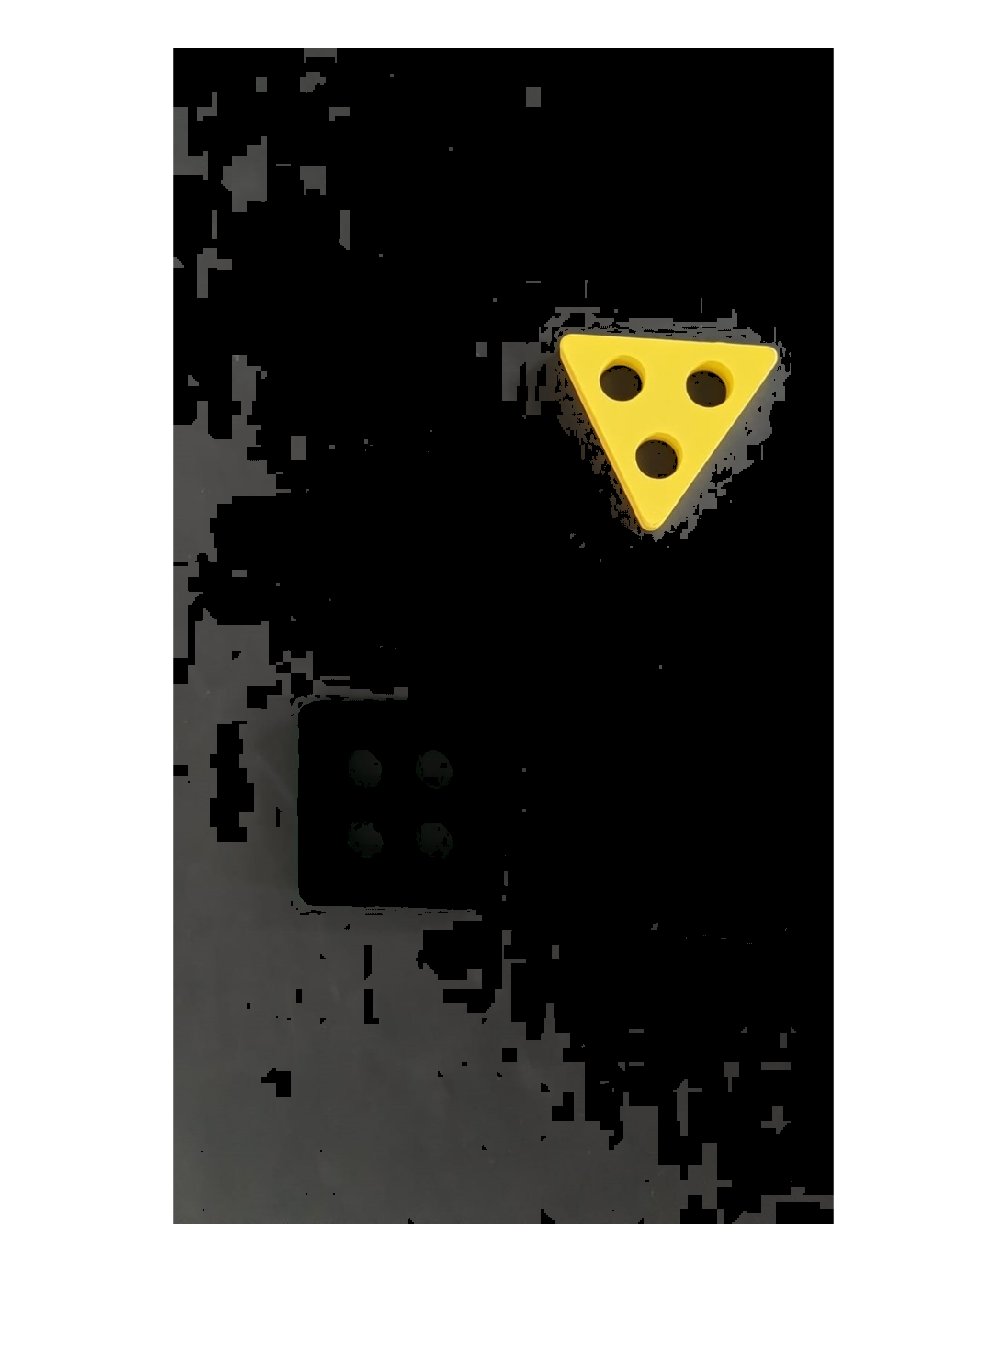


% Paso 5: Visualizar los resultados
% figure;
% subplot(2, 2, 1);

if Color == "Rojo"
    I_color = Img.*repmat(uint8(mascara_rojo), [1 1 3]);
% title('Detección de Rojo');
% 
% subplot(2, 2, 2);
elseif Color == "Verde"
    I_color = Img.*repmat(uint8(mascara_verde), [1 1 3]);
% title('Detección de Verde');
% 
% subplot(2, 2, 3);
elseif Color == "Azul"
    I_color = Img.*repmat(uint8(mascara_azul), [1 1 3]);
% title('Detección de Azul');
% 
% subplot(2, 2, 4);
elseif Color == "Amarillo"
    I_color = Img.*repmat(uint8(mascara_amarillo), [1 1 3]);
end

% Convierte la imagen a escala de grises (formato 2D)
I_color = im2double(I_color);

% Muestra la imagen en escala de grises
imshow(I_color);

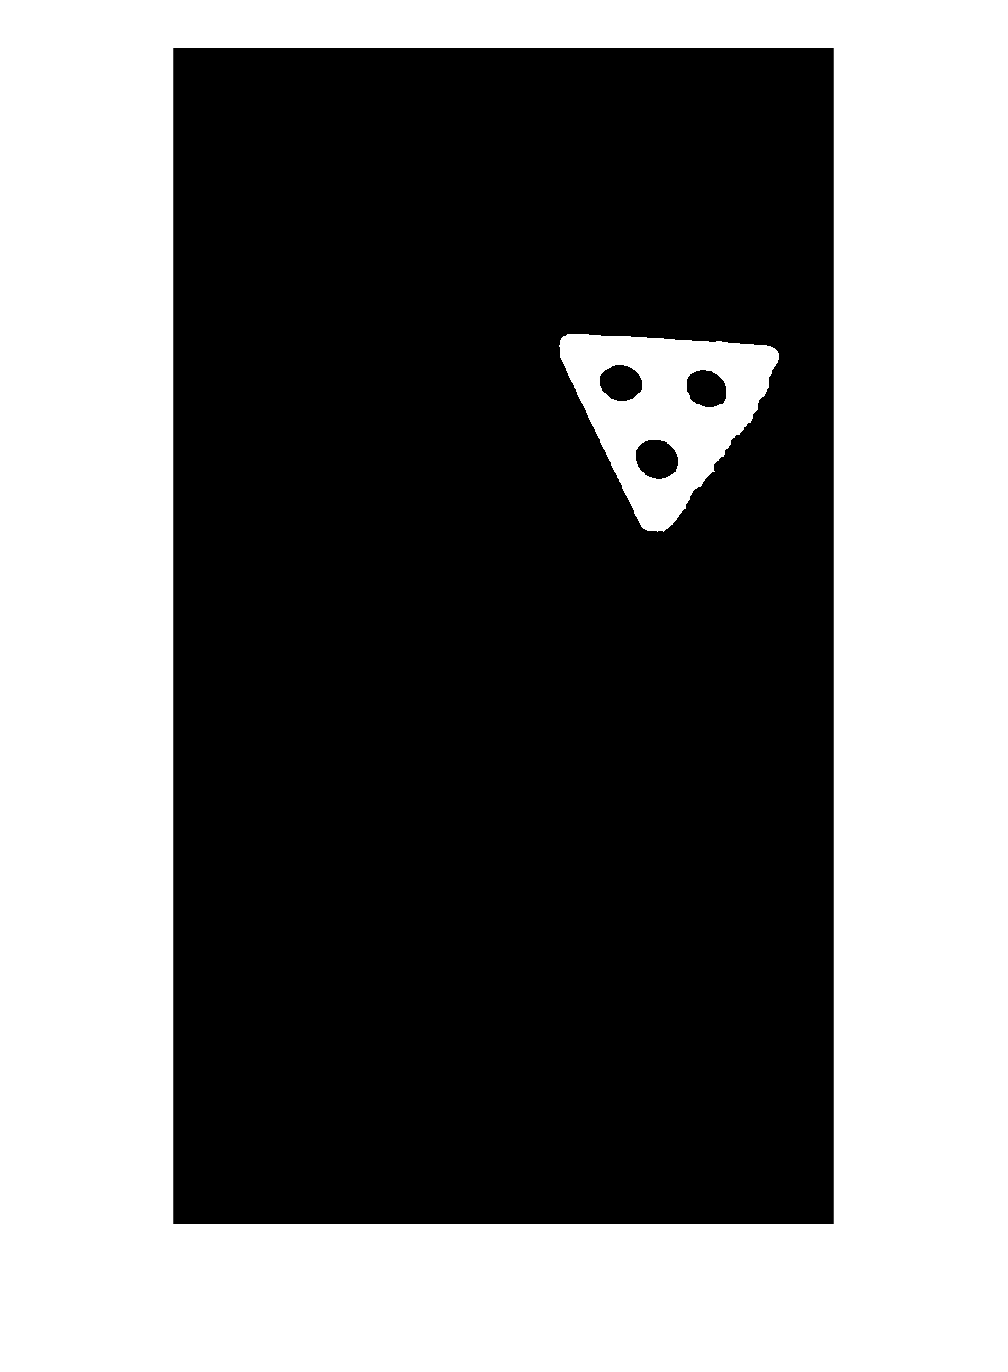


% title(['Detección de Amarillo']);
% 
% figure;
% imshow(Img);
% title('Imagen Original');
% hold on 

% Convertir la imagen a escala de grises
I_gray = rgb2gray(I_color);

% Aplicar filtro Wiener a cada canal de color por separado
for i = 1:3
    I_color(:,:,i) = wiener2(I_color(:,:,i), [50 50]);
end

% Convertir la imagen a binaria
I_binary = imbinarize(I_gray, 0.40);

% Eliminar ruido
I_binary = bwareaopen(I_binary, 130);

% Rellenar espacios de los objetos
se = strel('disk', 5);
I_binary = imclose(I_binary, se);
imshow(I_binary)
[B,L] = bwboundaries(I_binary, 'noholes');

figure
imshow(Img)

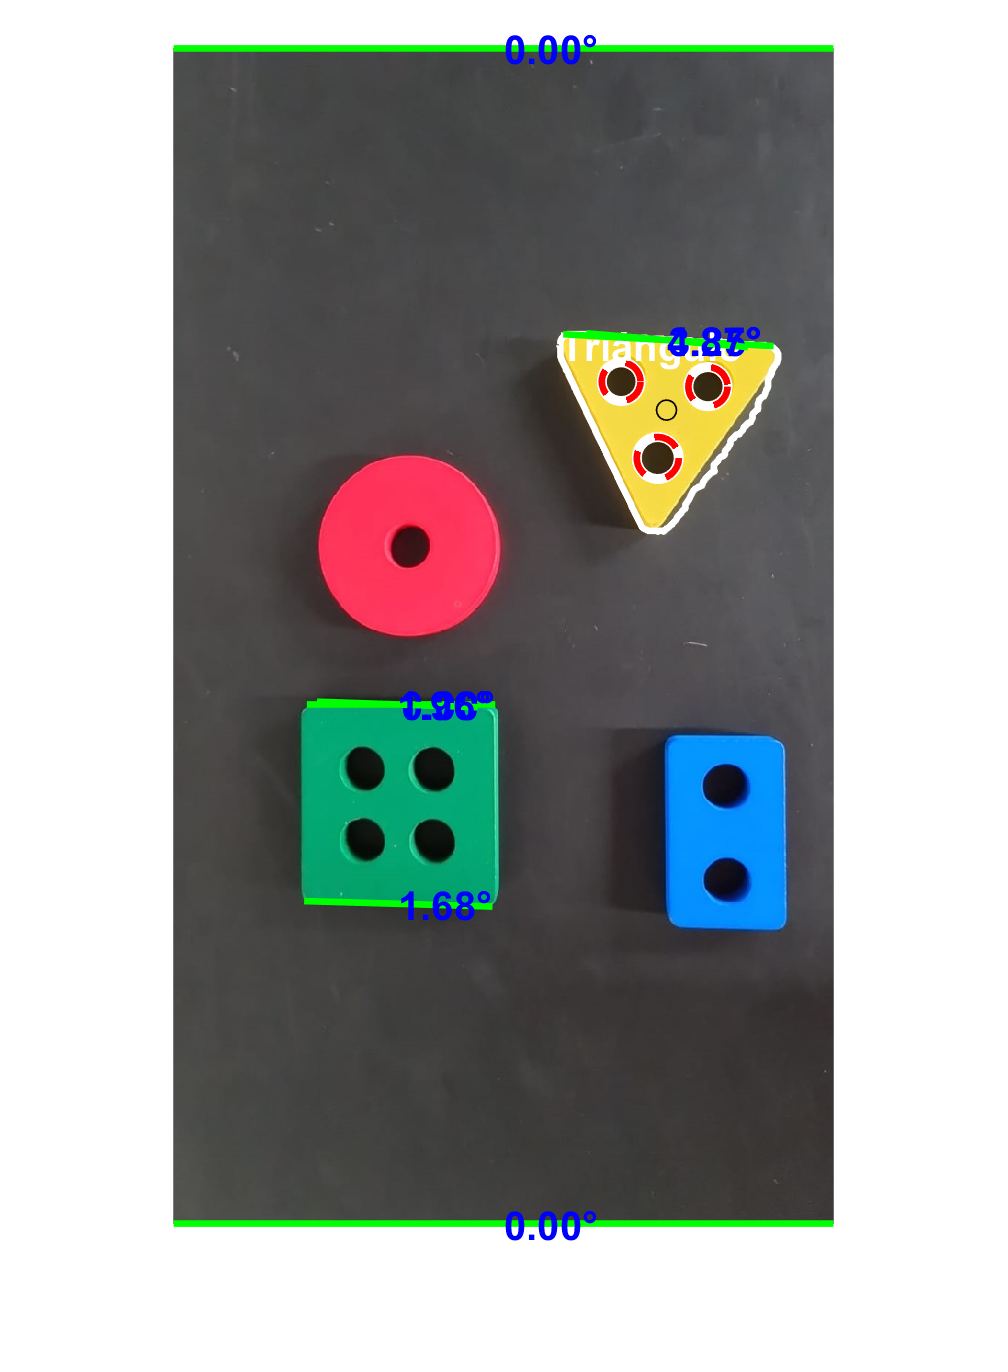

hold on

for k = 1:length(B),boundary = B{k}; % Ciclo para dibujar los contornos de las regiones 
    plot(boundary(:,2),boundary(:,1), 'w', 'LineWidth', 2)
end

% Extraemos la informacion de cada una de las regiones en este caso el Area 
% y el centro
stats = regionprops(L, 'Area', 'Centroid');
threshold = 0.20;
for k = 1:length(B)
    boundary = B{k};
    delta_sq = diff(boundary).^2;
    perimeter = sum(sqrt(sum(delta_sq,2))); %Extraemos perimetro
    area = stats(k).Area; %Extraemos el Area
    metric = 4*pi*area/perimeter^2; %Extraemos la metrica con el area y el perimetro
    if metric > threshold
        centroid = stats(k).Centroid;
        plot(centroid(1), centroid(2), 'ko');
    end
end

% Inicializar una matriz para almacenar los conteos de círculos oscuros
conteoCirculos = zeros(length(B), 1);

% Definimos el rango del radio
Rmin = 6;
Rmax = 29;

% Solicitar al usuario el número de centros a visualizar
figuraUsuario = input('Ingrese la figura que necesita (Cuadrado, Triángulo, Rectángulo, Círculo): ', "s");

if figuraUsuario == "Cuadrado"
    numCentrosUsuario = 4;
elseif figuraUsuario == "Triángulo"
    numCentrosUsuario = 3;
elseif figuraUsuario == "Rectángulo"
    numCentrosUsuario = 2;
elseif figuraUsuario == "Círculo"
    numCentrosUsuario = 1;
end

for k = 1:length(B)
    boundary = B{k};
    
    % Ciclo para dibujar los contornos de las regiones
    plot(boundary(:,2),boundary(:,1), 'w', 'LineWidth', 2);
    
    % Crear una máscara binaria para la región actual (por ejemplo, usando poly2mask)
    mask = poly2mask(boundary(:,2), boundary(:,1), size(I_color, 1), size(I_color, 2));
    
    % Encuentra todos los círculos oscuros de la imagen dentro del rango de radio.
    [DarkCenter, radiiDark] = imfindcircles(I_color, [Rmin Rmax], 'ObjectPolarity', 'dark');
    
    % Filtrar los círculos oscuros que están dentro del contorno actual
    circulosDentroContorno = [];
    for i = 1:numel(radiiDark)
        x = round(DarkCenter(i, 1));
        y = round(DarkCenter(i, 2));
        if mask(y, x) == 1
            circulosDentroContorno = [circulosDentroContorno; DarkCenter(i, :)];
        end
    end
    
    % Limitar el número de centros según la entrada del usuario
    circulosDentroContorno = circulosDentroContorno(1:min(numCentrosUsuario, size(circulosDentroContorno, 1)), :);
    
    % Etiquetar los círculos según la cantidad de centros
    numCentros = size(circulosDentroContorno, 1);
    if numCentros == 4
        etiqueta = "Cuadrado";
    elseif numCentros == 3
        etiqueta = "Triángulo";
    elseif numCentros == 2
        etiqueta = "Rectángulo";
    elseif numCentros == 1
        etiqueta = "Círculo";
    end
    
    % Dibujar líneas azules alrededor de los círculos oscuros dentro del contorno
    viscircles(circulosDentroContorno, radiiDark(1:numCentros), 'LineStyle', '--');
    
    % Mostrar la etiqueta en la imagen
    text(boundary(1, 2), boundary(1, 1), etiqueta, 'Color', 'white', 'FontSize', 12, 'FontWeight', 'bold');
    
    % Almacenar el número de círculos oscuros encontrados dentro del contorno actual
    conteoCirculos(k) = numCentros;
end

% Definir los filtros de Kirsch para las direcciones N, NW, W, SW, S, SE, E, NE
N=[-3, -3, 5; -3, 0, 5; -3, -3, 5];
NW=[-3, 5, 5; -3, 0, 5; -3, -3, -3];
W=[5, 5, 5; -3, 0, -3; -3, -3, -3];
SW=[5, 5, -3; 5, 0, -3; -3, -3, -3];
S=[5, -3, -3; 5, 0, -3; 5, -3, -3];
SE=[-3, -3, -3; 5, 0, -3; 5, 5, -3];
E=[-3, -3, -3; -3, 0, -3; 5, 5, 5];
NE=[-3, -3, -3; -3, 0, 5; -3, 5, 5];

% Convertir la imagen a escala de grises
if size(Img, 3) == 3
    Img = rgb2gray(Img);
end

% Aplicar los filtros de Kirsch en todas las direcciones
n = imfilter(Img, N);
nw = imfilter(Img, NW);
w = imfilter(Img, W);
sw = imfilter(Img, SW);
s = imfilter(Img, S);
se = imfilter(Img, SE);
e = imfilter(Img, E);
ne = imfilter(Img, NE);

% Sumar los resultados de los filtros de Kirsch
Kirsh_sum = n + nw + w + sw + s + se + e + ne;

% Binarizar
bin_sum = imbinarize(Kirsh_sum);

% Ajustar valores para mostrar correctamente
Kirsh_sum(Kirsh_sum > 200) = 255;
Kirsh_sum(Kirsh_sum < 200) = 0;

% Aplicar la transformada de Hough para detectar líneas
[H, theta, rho] = hough(Kirsh_sum, 'RhoResolution', 1, 'Theta', -90:0.05:89);
peaks = houghpeaks(H, 30, 'Threshold', 1);
lines = houghlines(Kirsh_sum, theta, rho, peaks, 'FillGap', 5, 'MinLength', 7);

% Definir valores mínimos de longitud y ángulo para filtrar líneas
min_length = 150;
min_angle = -45;
max_angle = 45;

% Mostrar las líneas
for k = 1:length(lines)
    xy = [lines(k).point1; lines(k).point2];
    len = norm(lines(k).point1 - lines(k).point2);
    angle = atan2(diff(xy(:,2)), diff(xy(:,1))) * 180 / pi;

    % Filtrar líneas por longitud y ángulo
    if len > min_length && angle > min_angle && angle < max_angle
        plot(xy(:,1), xy(:,2), 'LineWidth', 2, 'Color', 'green');
        text(mean(xy(:,1)), mean(xy(:,2)), sprintf('%.2f°', angle), ...
             'Color', 'blue', 'FontSize', 12, 'FontWeight', 'bold');
    end
end
hold off

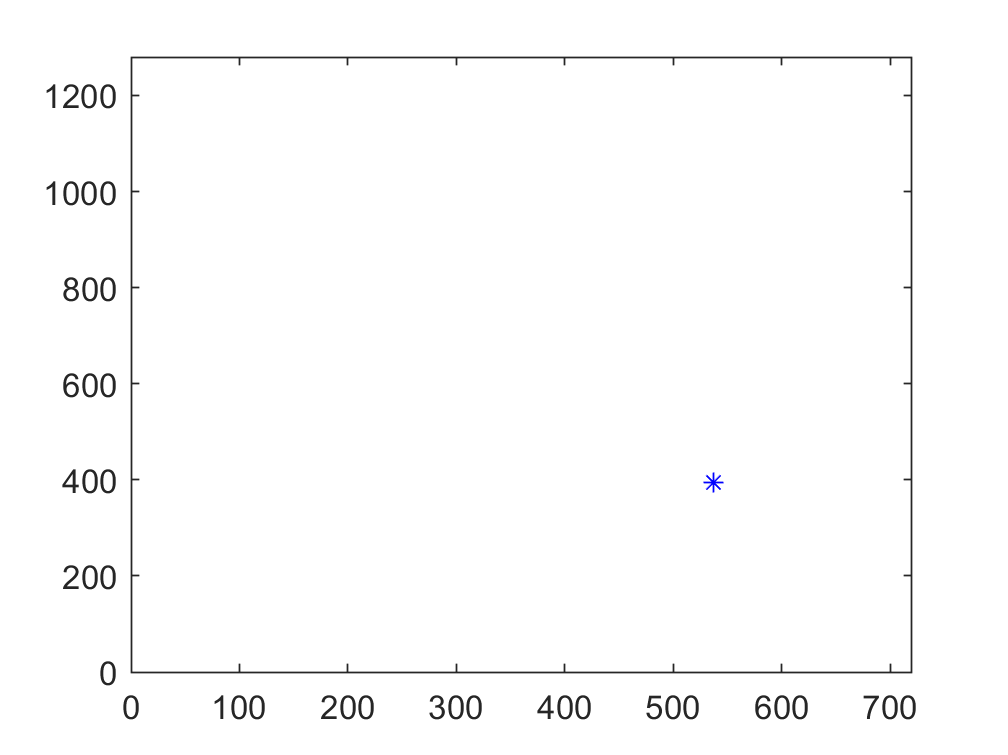


% Crear una matriz para almacenar las coordenadas de los centroides
centroids = zeros(numel(stats), 2);
% Almacenar las coordenadas de los centroides en la matriz
for x = 1:numel(stats)
    centroids(x,:) = stats(x).Centroid;
end

figure;
plot(centroids(:,1), centroids(:,2), 'b*')
axis([0 720 0 1280]);


% Convertir las coordenadas de píxeles a centímetros
factor_conversion = 5 / 207; % Cada 5 cm son 207 píxele
coordenadas_cm = centroids * factor_conversion;

% Mostrar las coordenadas en centímetros
disp('Coordenadas en Centímetros:');

Coordenadas en Centímetros:


disp(coordenadas_cm);

   12.9813    9.5322




% Guardar las coordenadas en una matriz (si deseas)
matriz_coordenadas = coordenadas_cm;